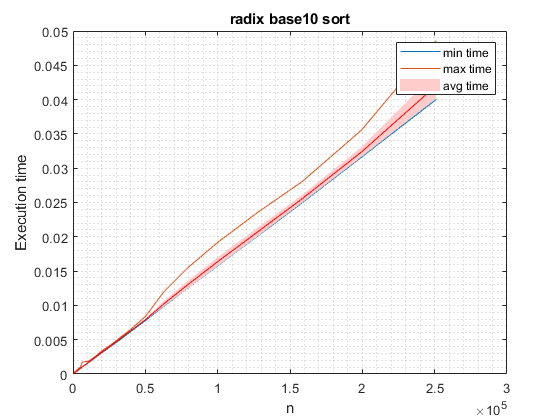

% Ver sort by sort

clear all;
sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];

s = 6;                                                          % escolher posição do sort no array k se pretende avaliar 

results = load(strcat("./sorts/",sorts(s),"_sort"));

for k = 2:3
    plot(results(:,1),results(:,k));
    hold on;
end

boundedline(results(:,1),results(:,4),results(:,5),'r');               % std dev no avg time

hold off;
grid("minor");
xlabel("n");
ylabel("Execution time");
legend("min time","max time","avg time");
title(strrep(strcat(sorts(s),"_sort"),"_"," "));

  %saveas(gcf,strcat(sorts(s),".png"));         %Uncomment to save image

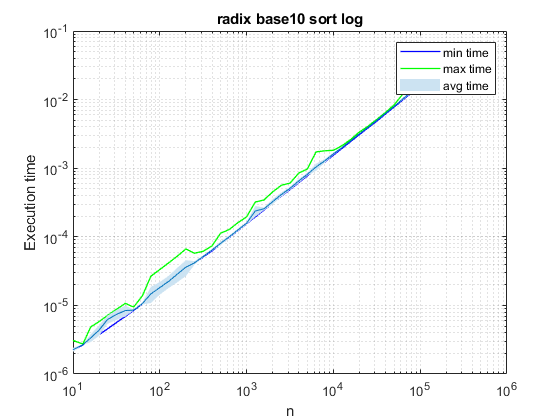

% Ver sort by sort log

sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];
cores = [ 'r' 'b' 'g'];
s = 6;                                                          % escolher posição do sort no array k se pretende avaliar
results = load(strcat("./sorts/",sorts(s),"_sort"));
for k = 2:3
    loglog(results(:,1),results(:,k),cores(k),'LineStyle','-', 'Color', cores(k),'linewidth', 1);
    hold on;
end

boundedline(results(:,1),results(:,4),results(:,5));               % std dev no avg time

hold off;
  
grid("minor");
xlabel("n");
ylabel("Execution time");
legend("min time","max time","avg time");
title(strrep(strcat(sorts(s),"_sort log"),"_"," "));

%saveas(gcf,strcat(sorts(s),"_log",".png"));         %Uncomment to save image

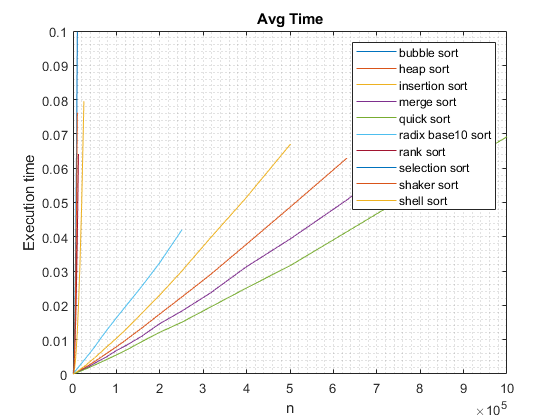

% Comparar tds os sorts

clear all;
sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];
data = ["Min time","Max time" ,"Avg Time"];
d = 3;                                                                  % escolher o indice da data k se pretende comparar 

for s = sorts
    results = load(strcat("./sorts/",s,"_sort"));
    plot(results(:,1),results(:,d + 1));
    hold on;
end
hold off;
grid("minor");
xlabel("n");
ylabel("Execution time");
legend(strrep(strcat(sorts,"_sort"),"_"," "));
title(data(d));

%saveas(gcf,strcat(data(d),".png"));                                     %Uncomment to save image

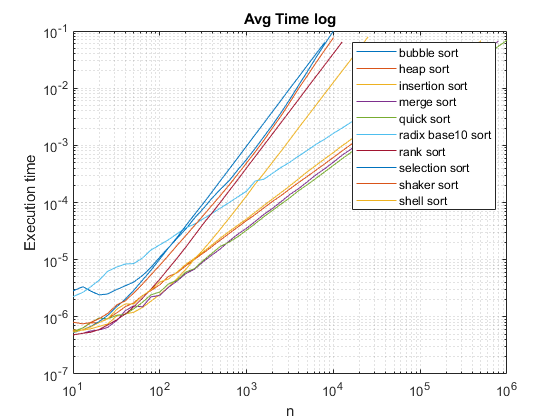

% Comparar tds os sorts log

sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];
data = ["Min time","Max time" ,"Avg Time"];
d = 3;                                                                  % escolher o indice da data k se pretende comparar 

for s = sorts
    results = load(strcat("./sorts/",s,"_sort"));
    loglog(results(:,1),results(:,d + 1));
    hold on;
end

hold off;
grid("minor");
xlabel("n");
ylabel("Execution time");
legend(strrep(strcat(sorts,"_sort"),"_"," "));
title(strcat(data(d)," log"));

%saveas(gcf,strcat(data(d),"_log",".png"));                                     %Uncomment to save image

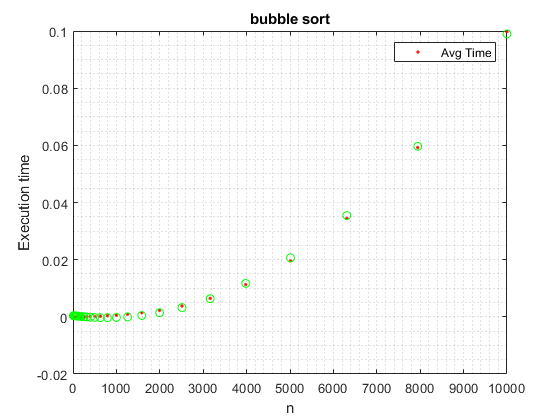

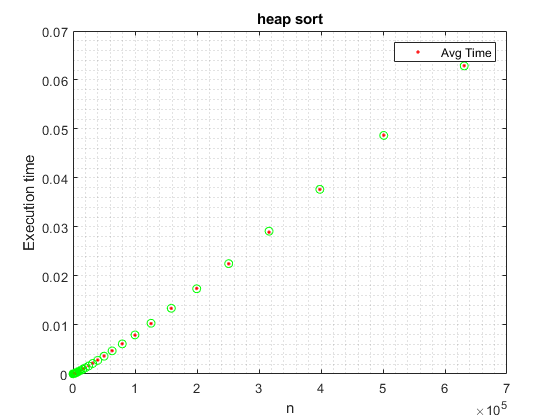

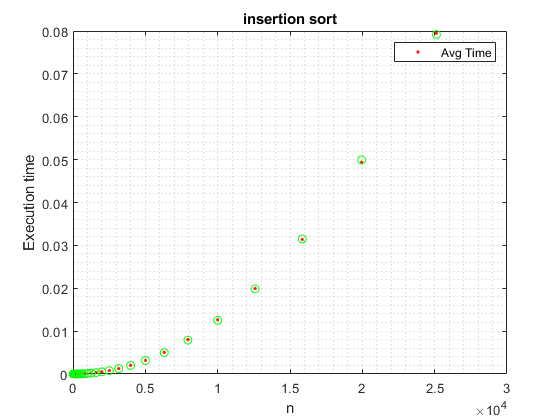

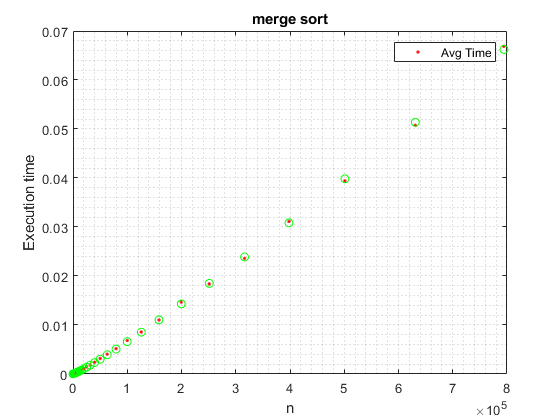

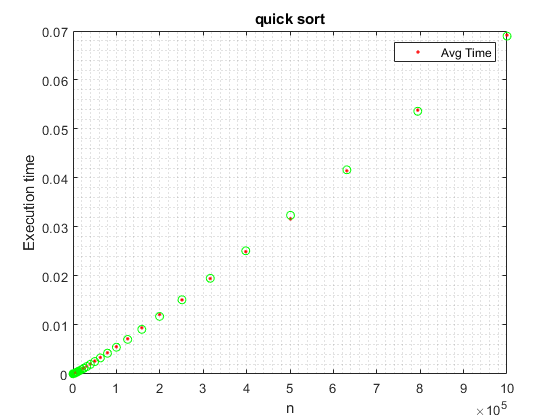

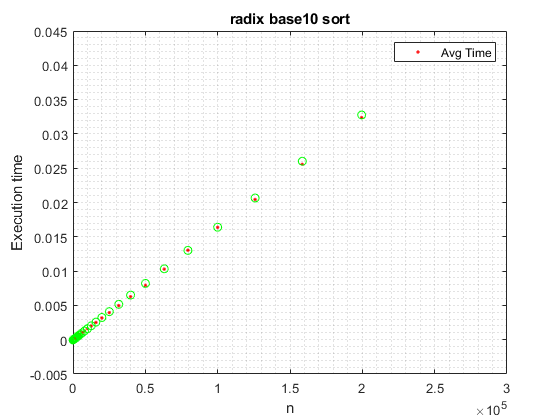

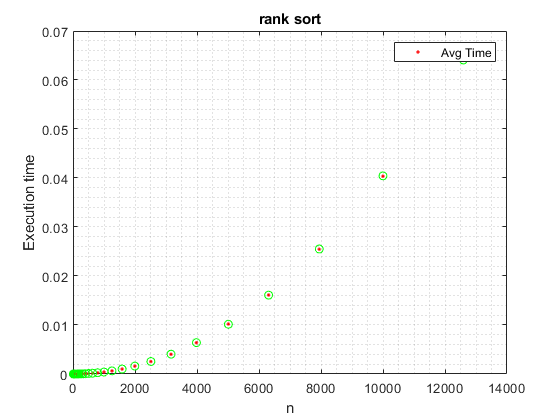

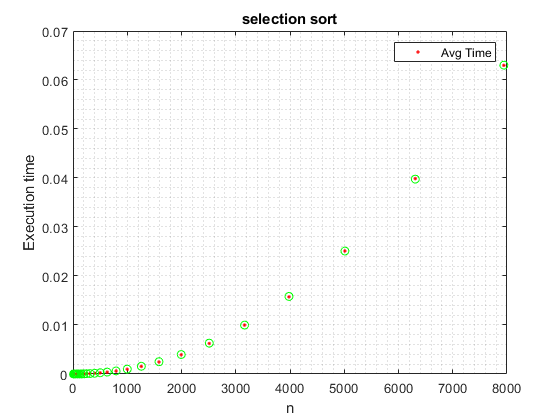

% Least Square Fit

clear all;
sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];
data = ["Min time","Max time" ,"Avg Time"];
d = 3;                                                                  % escolher o indice da data k se pretende comparar 

for s = 1:length(sorts)
    results = load(strcat("./sorts/",sorts(s),"_sort"));
    x = results(:,1);                                                   % extract the first column
    y = results(:,d + 1);                                               % extract the second column
    switch (d)
        case 1                                                          % Minimum time
            switch(s)                                                   % chose option to run    
                case 6
                    X = [ x, 0*x+1 ];                                   % build the X matrix for y(x) = Bx + C                
                case {2,4,5}
                    X = [ x.*log(x), x, 0*x+1 ];                        % build the X matrix for y(x) = Bx*log(x) + C
                case {3}
                    X = [ x.^2, x, 0*x+1 ];                             % build the X matrix for y(x) = Ax^2 + Bx + C       
                case {1,7,8,9} 
                    X = [ x.^2 , 0*x+1];                                % build the X matrix for y(x) = Ax^2 + c 
                case 10
                    X = x.*log(x);
                otherwise
                    fprintf('ERROR in d: %d\n',d);
            end
        case 2                                                          % Maximum time
            switch(s)                                                   % chose option to run    
                case {1,3}
                    X = [ x.^2, x, 0*x+1 ];                             % build the X matrix for y(x) = Ax^2 + Bx + C        
                case {2,4,5}
                    X = [ x.*log(x), x, 0*x+1 ];                        % build the X matrix for y(x) = Bx*log(x) + C        
                case {7,8,9} 
                    X = x.^2;                                           % build the X matrix for y(x) = Ax^2 
                case 6
                    X = [ x, 0*x+1 ];                                   % build the X matrix for y(x) = Bx + C
                case 10
                    X = [ x.*log(x).^2, 0*x+1 ];                        % build the X matrix for y(x) = B*x*log(x) +c
                otherwise
                    fprintf('ERROR in d: %d\n',d);
            end
        case 3                                                          % Average Time
            switch(s)                                                   % chose option to run    
                case {1,3}
                    X = [ x.^2, x, 0*x+1 ];                             % build the X matrix for y(x) = Ax^2 + Bx + C        
                case {2,4,5}
                    X = [ x.*log(x), x, 0*x+1 ];                        % build the X matrix for y(x) = Bx*log(x) + C         
                case 6 
                    X = [ x, 0*x+1 ];                                   % build the X matrix for y(x) = Bx + C
                case {7,8,9} 
                    X = x.^2;                                           % build the X matrix for y(x) = Ax^2
                case 10
                    X = [ x.*log(x).^2, 0*x+1 ];                        % build the X matrix for y(x) = B*x*log(x) +c
                otherwise
                    fprintf('ERROR in d: %d\n',d);
            end 
    end
    w = pinv(X)*y;                                                      % optimal solution (could also be written as w = X \ y;)
    e = y-X*w;                                                          % optional: compute the errors vector
    format long;
    w;                                                                  % print w --- A = w(1), B = w(2), and C = w(3)
    norm(e);                                                            % optional: print the norm of the error vector (square root of the sum of squares)
    plot(x,y,'.r',x,X*w,'og');                                          % plot the original data and its best least squares approximation
    grid("minor");
    xlabel("n");
    ylabel("Execution time");
    legend(data(d));
    title(strrep(strcat(sorts(s),"_sort"),"_"," "));
    figure;
    %saveas(gcf,strcat(s,"_sort","_lst",".png"));                              %Uncomment to save image 
end